%2025.09.05
%产生灵巧噪声（噪声*ISRJ）干扰作为分类数据，干噪比30-60dB之间随机；
%噪声乘积干扰(NPJ, noise product jamming)
close all;clear;clc
j=sqrt(-1);
data_num=1;   %干扰样本数
samp_num=8000;%距离窗点数
fs = 80e6; %采样频率
B = 10e6;  %信号带宽
taup = 20e-6; %信号脉宽
t = linspace(0,taup,taup*fs);          %时间序列
fc = 40e6

fc = 40000000

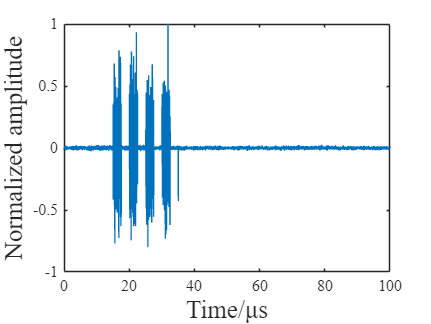

window = 128

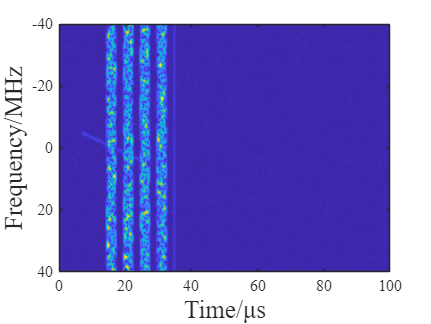

f0 = fc - B/2;   % 起始频率
f1 = fc + B/2;   % 终止频率
lfm = exp(1j*2*pi*(f0*t + (B/(2*taup))*t.^2));

SNR=0; %信噪比dB
echo=zeros(data_num,samp_num,3);     %矩阵大小（500,samp_num,2）
echo_stft=zeros(data_num,100,247,3);  %矩阵大小（500,200,1000,2）
num_label = 4;
label=zeros(1,data_num)+num_label;                         %标签数据,此干扰标签为0

repetion_times=[4,3,2,1];
period=[5e-6,10e-6];
duty=[20,25,33.33,50];

for m=1:data_num
    
    JNR=30+round(rand(1,1)*30); %干噪比30-60dB
    sp=randn([1,samp_num])+1j*randn([1,samp_num]);%噪声基底
    sp=sp/std(sp);
    sp1=sp;                %灵巧噪声备用
    As=10^(SNR/20);%目标回波幅度
    Aj=10^(JNR/20);  %干扰回波幅度
    range_tar=1+round(rand(1,1)*1400);
    sp(1+range_tar:length(lfm)+range_tar)=sp(1+range_tar:length(lfm)+range_tar)+As*lfm;  %噪声+目标回波 目标在距离窗内 range_tar点处
    index1=1+round(rand(1,1));
    index2=1+round(rand(1,1)*3);
    period1=period(index1);
    duty1=duty(index2);
    repetion_times1=repetion_times(index2);
    squa=(square((1/period1)*2*pi*t, duty1)+1)/2;
    squa(400)=0;
    squa1=lfm.*squa;
    delay_time=period1*duty1*0.01;
    delay_num=ceil(delay_time*fs);
    for i=1:repetion_times1 %多次转发
        left_range = range_tar+400+i*delay_num;
        right_range = left_range+length(t)-1;
        sp(left_range:right_range)=sp(left_range:right_range)+Aj*squa1.*sp1(1:length(t));
        
    end
    

    sp=sp/max(max(sp));
    sp_abs=abs(sp);
    figure(3)
    plot(linspace(0,100,samp_num),sp);
    set(gca,'FontName','Times New Roman');
    xlabel('Time/μs','FontSize',15);ylabel('Normalized amplitude','FontSize',15)
    
    echo(m,1:samp_num,1)=real(sp); 
    echo(m,1:samp_num,2)=imag(sp);
    echo(m,1:samp_num,3)=sp_abs;
    echo(m,1:samp_num,4)=angle(sp);%信号实部、虚部分开存入三维张量中
    
    window = 128    
    [S,F,T] = spectrogram(sp,window,window-8,400,fs);
    
    S=S/max(max(S));
    S_abs=abs(S);
    figure(4)
    imagesc(linspace(0,100,size(S,1)),linspace(-40,40,size(S,2)),abs(S));
    set(gca,'FontName','Times New Roman');
    xlabel('Time/μs','FontSize',15);ylabel('Frequency/MHz','FontSize',15)
   
    %     figure(5)
    % imagesc(linspace(0,100,size(S,1)),linspace(-10,10,size(S,2)),real(S));
    % set(gca,'FontName','Times New Roman');
    % xlabel('Time/μs','FontSize',15);ylabel('Frequency/MHz','FontSize',15)
    % 
    %     figure(6)
    % imagesc(linspace(0,100,size(S,1)),linspace(-10,10,size(S,2)),imag(S));
    % set(gca,'FontName','Times New Roman');
    % xlabel('Time/μs','FontSize',15);ylabel('Frequency/MHz','FontSize',15)
    % 
    %     figure(7)
    % imagesc(linspace(0,100,size(S,1)),linspace(-10,10,size(S,2)),angle(S));
    % set(gca,'FontName','Times New Roman');
    % xlabel('Time/μs','FontSize',15);ylabel('Frequency/MHz','FontSize',15)
    
    echo_stft(m,1:size(S,1),1:size(S,2),1)=real(S);
    echo_stft(m,1:size(S,1),1:size(S,2),2)=imag(S);
    echo_stft(m,1:size(S,1),1:size(S,2),3)=S_abs;
    echo_stft(m,1:size(S,1),1:size(S,2),4)=angle(S);
    
end

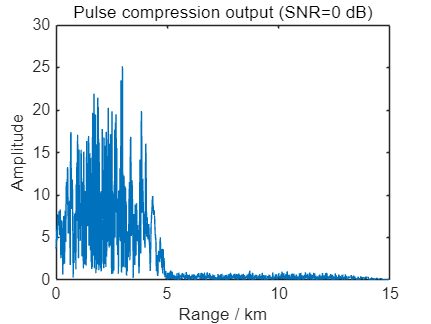

% --- 匹配滤波脉冲压缩 ---
s_ref = lfm;                    % 参考信号 (一定要和生成时一致)
h = conj(flip(s_ref));
y = conv(sp, h);
Np = length(s_ref);
y_aligned = y(Np:end);          % 对齐
env = abs(y_aligned);
env_dB = 10*log10(env.^2 / max(env.^2));


% 距离轴
c = 3e8;
rng_axis = (0:length(env)-1) * c/(2*fs);

% 绘图
figure;
% plot(rng_axis*1e-3, env_dB);
% xlabel('Range / km'); ylabel('Power (dB)');

plot(rng_axis*1e-3, env);
xlabel('Range / km'); ylabel('Amplitude');
title(sprintf('Pulse compression output (SNR=%d dB)', SNR));